El US0-016 es capaz de medir distancias de entre 20 y 4000 milímetros.

Representamos la recta ideal de medidas (si el sensor fuese perfecto) con respecto a la obtenida experimentalmente.Realizamos la calibración simultanea 

Realizaremos la calibración simultanea de los dos sensores. Para identificarlos, los distingueremos como sensor izquierdo (**"L"**) y sensor derecho ("**R**").

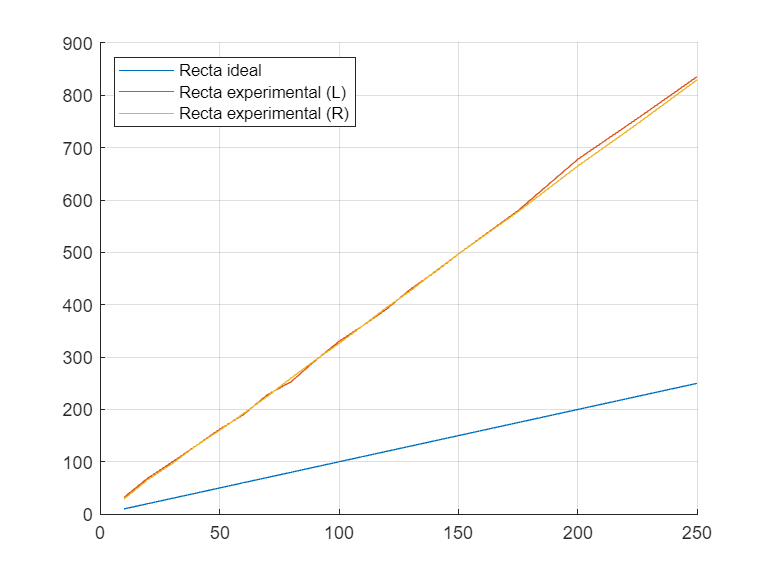

distancia_teorica=[10, 20, 30, 40, 50, 60, 70, 80, 90, 100, 110, 120, 130, 140, 150, 175, 200, 225, 250];
distancia_medida_L = [32, 69, 99, 130, 162, 190, 228, 253, 293, 330, 360, 392, 430, 462, 497, 580, 678, 756, 836];
distancia_medida_R = [29, 66, 96, 130, 160, 192, 225, 260, 294, 326, 360, 395, 427, 463, 497, 578, 665, 746, 830];figure()
grid on
hold on
plot(distancia_teorica,distancia_teorica)
plot(distancia_teorica,distancia_medida_L)
plot(distancia_teorica,distancia_medida_R)
legend("Recta ideal", "Recta experimental (L)", "Recta experimental (R)",'Location','northwest')
hold off

Ahora, realizamos una regresión lineal para obtener la ecuacion de ajuste de los datos experimentales de cada sensor.

% ajustamos a una recta ya que es el polinomio que mejor se ajusta a simple vitsa
pol_L= polyfit(distancia_teorica,distancia_medida_L,1) 

pol_L =     3.3698   -6.8969


pol_R = polyfit(distancia_teorica,distancia_medida_R,1) 

pol_R =     3.3396   -5.6439


Representamos las rectas de ajuste con la ideal

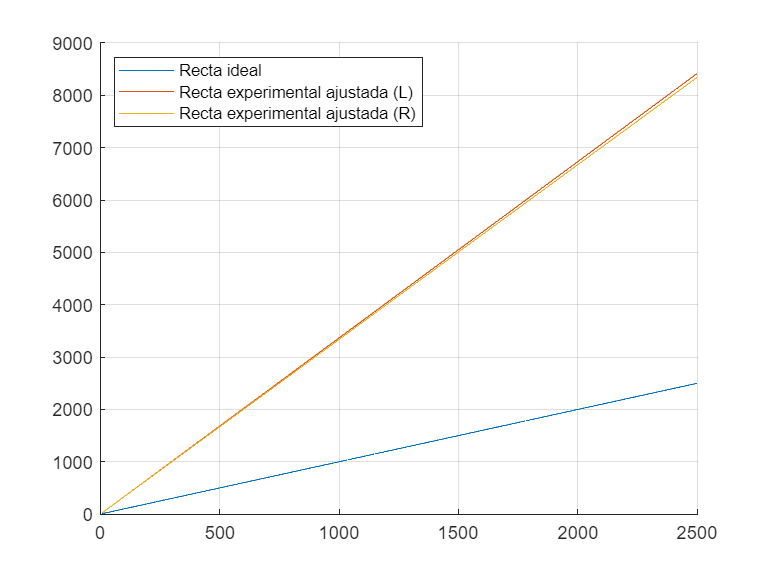

x = 10:1:2500;
y_teo = polyval([1 0],x);
y_exp_L = polyval(pol_L,x);
y_exp_R = polyval(pol_R,x);

figure()
grid on
hold on
plot(x,y_teo)
plot(x,y_exp_L)
plot(x,y_exp_R)
legend("Recta ideal","Recta experimental ajustada (L)", "Recta experimental ajustada (R)", 'Location','northwest')
hold off

Para ajustar la recta del sensor a la teórica, realizaremos un ajuste de 0 y de ganancia:

cero_L = 0-polyval(pol_L,0)

cero_L = 6.8969

cero_R = 0-polyval(pol_R,0)

cero_R = 5.6439

pol_L(1,2) = pol_L(1,2)+cero_L;
pol_R(1,2) = pol_R(1,2)+cero_R;

K_L = 400/polyval(pol_L,400)

K_L = 0.2968

K_R = 400/polyval(pol_R,400)

K_R = 0.2994